计算高阻抗表面对入射波的反射系数的相位

创建者：FTT

创建日期：2024.12.12

clear
clc
close all

HIS参数

D = 2e-3; %栅格周期
w = 0.2e-3; %条带宽度
d = 1e-3; %基板厚度
epsr = 10.2; %基板介电常数

常量

eps0 = 8.854*1e-12;
mu0 = 4*pi*1e-7;
c0 = 1/sqrt(eps0*mu0);
eta0 = sqrt(mu0/eps0);

扫频范围

f = linspace(8e9, 18e9, 1000);
omega = 2*pi*f;
k0 = omega/c0; %真空波数

入射波

theta = 85*pi/180; %入射角
kt = k0*sin(theta); %切向波数分量

中间量

epseff = (epsr+1)/2; %等效均匀介电常数
keff = k0*sqrt(epseff); %等效介质中的波数
etaeff = eta0/sqrt(epseff); %等效介质中的波阻抗
alpha = keff*D/pi*log(1/sin(pi*w/2/D)); %栅格常数
k = k0*sqrt(epsr); %基板中的波数
beta = sqrt(k.^2 - kt.^2); %基板中的法向传播常数
theta2 = asin(sin(theta)/sqrt(epsr)); %根据折射定律计算的角度，论文式（22）

输入阻抗

ZinpTM = 1i*omega.*mu0.*tan(beta*d)./beta.*cos(theta2)^2./(1-2*keff.*alpha.*tan(beta*d)./beta*cos(theta2)^2); %TM输入阻抗，论文式（20）
ZinpTE = 1i*omega.*mu0.*tan(beta*d)./beta./(1-2*keff.*alpha.*tan(beta*d)./beta*(1-2/(epsr+1)*sin(theta)^2)); %TM输入阻抗，论文式（23）

自由空间阻抗

Z0TM = eta0.*cos(theta); %TM极化自由空间波阻抗，论文式（13）
Z0TE = eta0./cos(theta); %TE极化自由空间波阻抗，论文式（12）

使用传输线模型计算反射系数

RTM = (ZinpTM-Z0TM)./(ZinpTM+Z0TM);
RTE = (ZinpTE-Z0TE)./(ZinpTE+Z0TE);

绘图

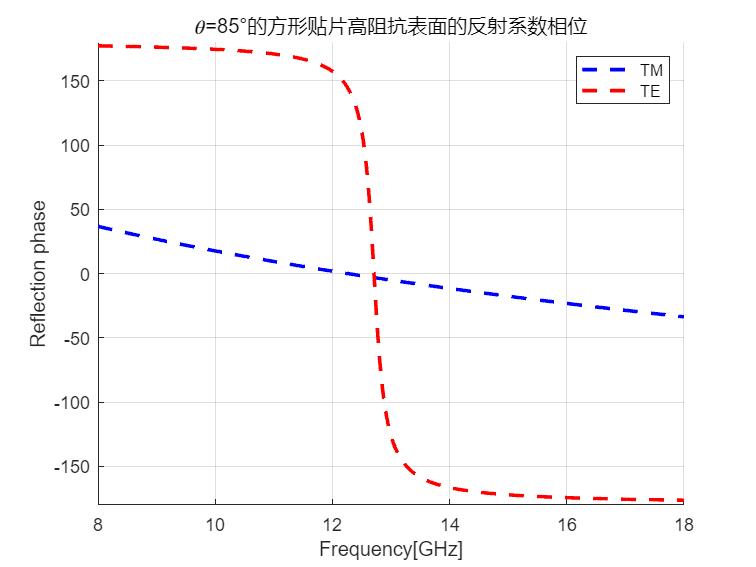

h1 = figure;
hold on
plot(f/1e9, phase(RTM)*180/pi, 'b--', 'LineWidth', 2)
plot(f/1e9, phase(RTE)*180/pi, 'r--', 'LineWidth', 2)
xlabel('Frequency[GHz]')
ylabel('Reflection phase')
legend('TM','TE')
title(strcat('\theta=',num2str(theta*180/pi),'°的方形贴片高阻抗表面的反射系数相位'))
xlim([8 18])
ylim([-180 180])
grid on